# lora sim

## lora parameters

clear
SF=12;
numSym=3;
BW=125e3;%samples per sec
Fs=BW;
SPS=(2^SF);%samples per lora symbol



## simulation parameters

dataLength=SF*numSym;
randomData=true;
nLoops=1;
filtersOn=false;
plotSpec=false;
maxSNR=22;
dopplerShift=00e3;


## transmitter

messageBits= randi([0 1],dataLength,1)

messageBits =      1
     1
     0
     1
     1
     0
     0
     1
     1
     1


%group in symbols, SF bits per symbol
messageSymbols=reshape(messageBits,[],SF)

messageSymbols =      1     1     0     1     1     0     1     0     1     0     1     0
     1     1     1     0     0     0     1     1     1     1     0     0
     0     0     1     1     1     1     1     1     1     0     0     1


loraSymbols=zeros(SPS,numSym);%%every colum contains the samples of one symbol
for i=1:numSym
    k=binaryVectorToDecimal(messageSymbols(i,:));
    for n=1:SPS
        if k >= SPS
            k=k-SPS;
        end 
        k = k+1;
        loraSymbols(n,i)=(1/(sqrt(2^SF)))*exp(1i*2*pi*k*(k/(2^SF*2)));
    end
end

txSignal=reshape(loraSymbols,[],1);

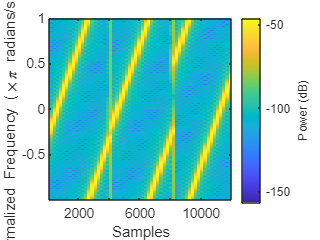


spectrogram(txSignal(1:3*(2^SF)),round((2^SF)/10),round(((2^SF)/10)/2),2^SF,'power','centered', 'yaxis');